This is a separate livescipt for estimating marker mediator effect during the pain delivery pahse between putamen activity and rating. This uses multilevel mediation. Some points of hte CanLabfunction's options needs to be clarified first:

% Bootstrapping/permutation options

% 'boottop'         In a single-level analysis, do bootstrap statistics (aka 'boot1')

% 'bootstrapfirst'  In a multi-level analysis, bootstrap first level stats

% 'bootsamples'     Number of bootstrap samples (default 1000)

% 'signperm'        Do sign permutation test at 2nd level (alternative to

%                   bootstrap)

%

% Multilevel options

% 'hierarchical'    multi-level model with weighing based on 1st level variance

% 'summarystats'    use summary-statistics approach with multi-level data;

% no weighting

Aslo think about to normalize the model input data: X and M?

Normalization does not change the statistical test results, but the coefficeints and teh corresponding t-values. Not sure which one is the correct one.

Maybe boottop? and hierarchical?

see my answers after the fitting and stats below:

# NPS

Mediation analysis

Observations:  17, Replications:  17
Predictor (X): Putact, Outcome (Y): Rating: Mediator (M): NPS

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: Yes
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 001
Bootstrapping:  Min p-value is 0.095600. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
002
Bootstrapping:  Min p-value is 0.144000. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
003
Bootstrapping:  Min p-value is 0.204800. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
004
Bootstrapping:  Min p-value is 0.183000. Adding   0 samples
 Done in   0 (s

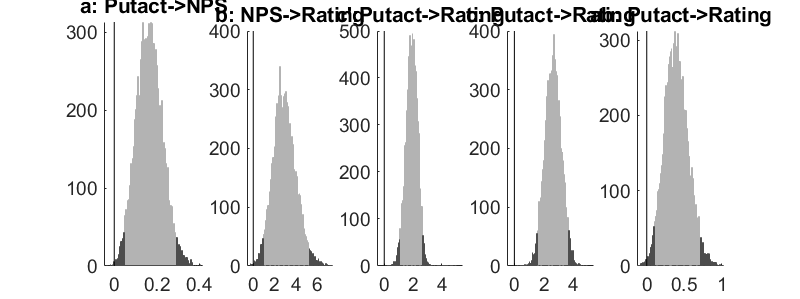

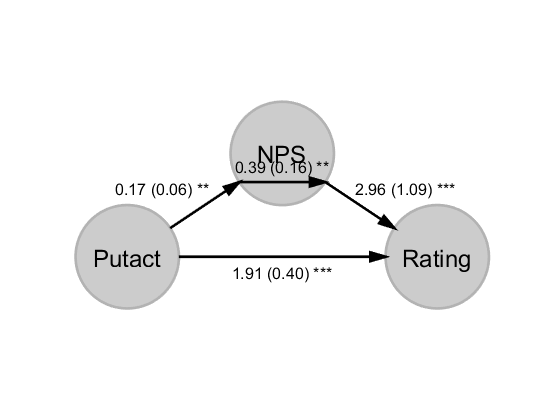

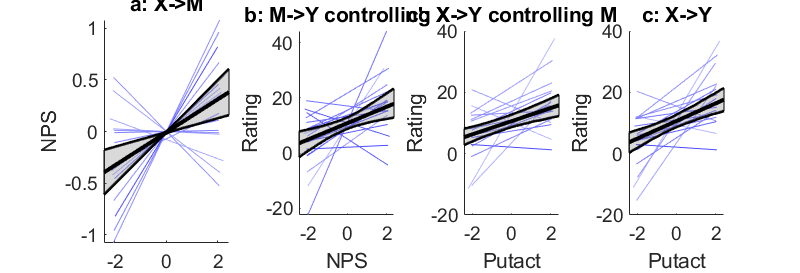

No second-level covariates; omitting 2nd level scatterplots.


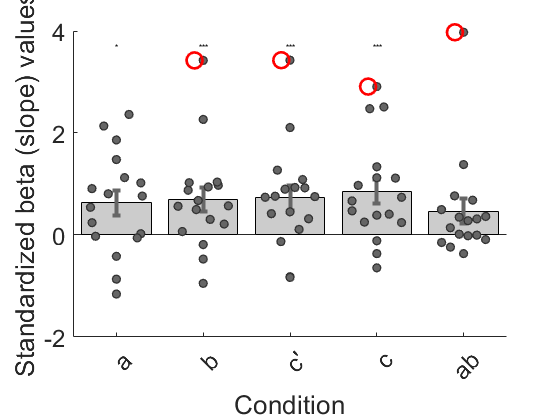

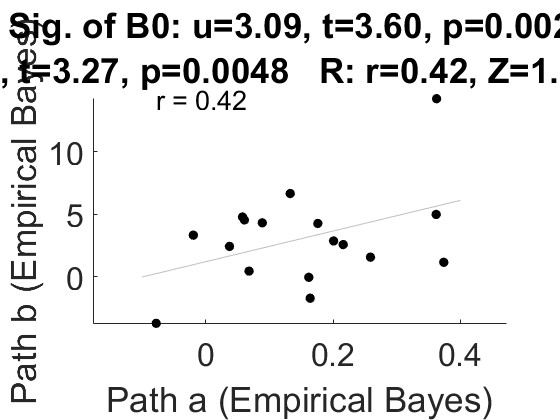


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	0.17	2.96	1.91	2.66	0.39	
STE	0.06	1.09	0.40	0.56	0.16	
t (~N)	2.70	2.71	4.74	4.74	2.48	
Z	3.28	3.80	3.36	3.67	3.09	
p	0.0010	0.0001	0.0008	0.0002	0.0020	

________________________________________
Total time:  15 s



%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...
% one has to load the mother of tables to get the data what is used here:
moderatorpath= "pain_placebo_minus_control.NPS";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = -df.putamensctivation{k,1}(:); %reverse rating: this would then mean control-placebo (so we end up higher activation in the control would mean a positive value)
        X{k} = (X{k} - mean(X{k},'omitnan')) ./ std(X{k},'omitnan');   % z-score
        M{k} = extractVectorFromPath(df, moderatorpath, k, true); %bc of the true option at the end: this would mean control-placebo,and higher value leads to higher effect (as NPS represent rather the nociceptive aspect of pain experience)
        M{k} = (M{k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating with the true option, meaning control-placebo.
%         Y{k} = (Y{k} - mean(Y{k},'omitnan')) ./ std(Y{k},'omitnan');   % z-score
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths_nps, stats_nps] = mediation(X, Y,M, ...
    'boot', 'verbose','plots',... %'plots', 
    'boottop','bootstrapfirst','bootsamples', 10000, 'hierarchical', ...
    'names', {'Putact'  'Rating' 'NPS'});

# SIIPS

Mediation analysis

Observations:  17, Replications:  17
Predictor (X): Putact, Outcome (Y): Rating: Mediator (M): SIIPS

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: Yes
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 001
Bootstrapping:  Min p-value is 0.043200. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
002
Bootstrapping:  Min p-value is 0.020400. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
003
Bootstrapping:  Min p-value is 0.262800. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
004
Bootstrapping:  Min p-value is 0.435000. Adding   0 samples
 Done in   0 

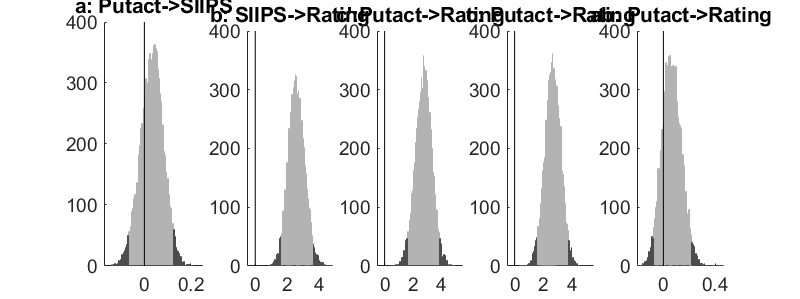

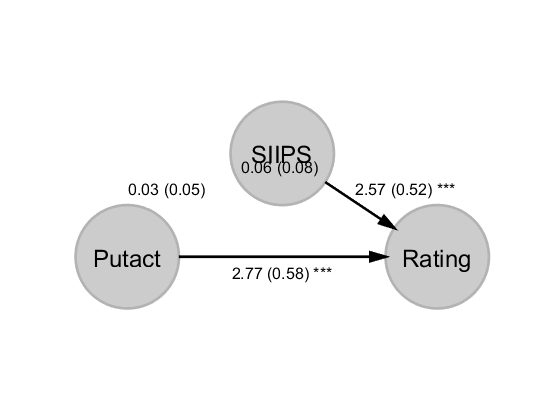

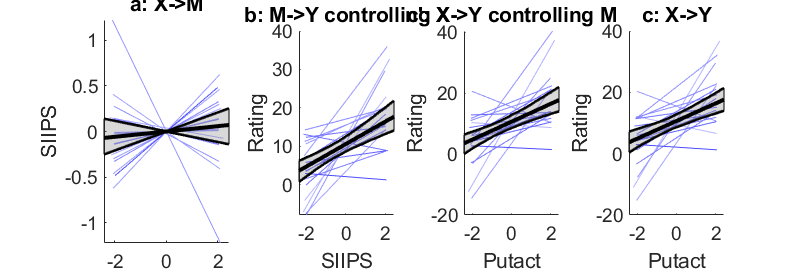

No second-level covariates; omitting 2nd level scatterplots.


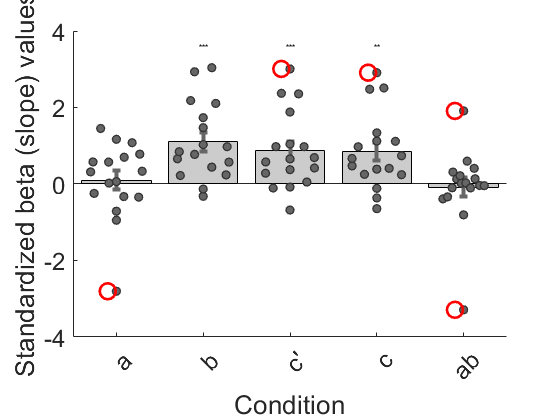

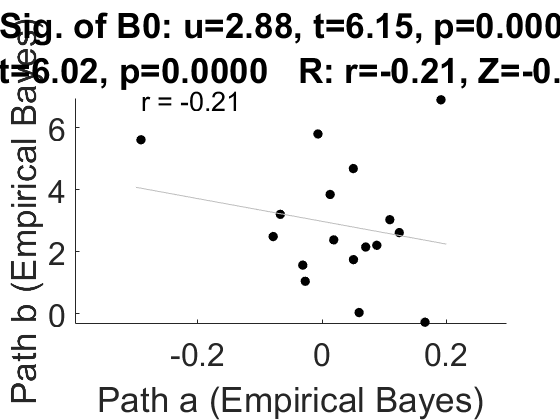


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	0.03	2.57	2.77	2.66	0.06	
STE	0.05	0.52	0.58	0.56	0.08	
t (~N)	0.65	4.99	4.77	4.80	0.85	
Z	0.58	3.95	3.60	3.67	0.90	
p	0.5618	0.0001	0.0003	0.0002	0.3688	

________________________________________
Total time:  14 s



%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...
% one has to load the mother of tables to get the data what is used here:
moderatorpath= "pain_placebo_minus_control.siips";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = -df.putamensctivation{k,1}(:);
        X{k} = (X{k} - mean(X{k},'omitnan')) ./ std(X{k},'omitnan');   % z-score
        M{k} = extractVectorFromPath(df, moderatorpath, k, true);
        M{k} = (M{k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating if needed
    
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths_siips, stats_siips] = mediation(X, Y,M, ...
    'boot', 'verbose','plots',... %'plots', 
    'boottop','bootstrapfirst','bootsamples', 10000, 'hierarchical', ...
    'names', {'Putact' 'Rating' 'SIIPS' });

# Conclusion of the findings above:

- the bootstrapping (based on llm discussion and the code itslef): 

-     the bootstrapfirst is doing a bootstrap on the first level(line 359): still respect group boundaries, so it would permute within on study (bootstrapping would not be violated)

-     boottop (second_level_bootstrap): in my understandind this is choice can be done in a two-stage like approach

- one can use either or both.

Regarding summary statistics:

- 'hierarchical'    multi-level model with weighing based on 1st level variance; 'summarystats'    use summary-statistics approach with multi-level data;

- I would go with hiearachical option. However, selectin summarystats would not change the ab effect significane in any of the markers.

Hierarhical option as we do have individual data with a decent number of subjects/study.

Simultaenous use of bootstrapping, at both levels. while this is the slowest based on copmutation, still it gives back the most robust results?

With these options, I have found that the anticipatory putamen activation, which was correlated with individual ratings, was mediated by the NPS but not woth SIIPS during pain delivery phase.

Note that: using the "non-normalized" rating (the GIV_stat_rating;which one after that normalize) ended up non-signfiicant result(but if we normalize it, with the similar fashion, the mediation results is still significant).

%saving the outputs
stats=stats_nps;
pathNames = stats.names';

T = array2table([stats.mean; stats.ste; stats.z; stats.p], ...
    'VariableNames', {'a','b','cp','c','ab'}, ...
    'RowNames', {'Coeff','STE','Z','p'});

disp(T)

                a            b             cp            c            ab    
             ________    __________    __________    __________    _________

    Coeff     0.16527        2.9612        1.9131        2.6637      0.39304
    STE      0.061106        1.0937         0.404       0.56152      0.15867
    Z          3.2833         3.801        3.3643        3.6674       3.0912
    p        0.001026    0.00014413    0.00076736    0.00024506    0.0019935




% Save
pathtosave = 'C:\Users\lenov\Documents\PICO\C_calculations\mygithubproject\anticipation_analysis\F_additionalanalysis\mediationanalysis\results'

pathtosave = 'C:\Users\lenov\Documents\PICO\C_calculations\mygithubproject\anticipation_analysis\F_additionalanalysis\mediationanalysis\results'

writetable(T, fullfile(pathtosave,'mediation_results_nps.csv'));
save(fullfile(pathtosave,'mediation_results_nps.mat'), 'paths_siips', 'stats_siips', 'T');


%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...
% one has to load the mother of tables to get the data what is used here:
moderatorpath= "pain_placebo_minus_control.NPS";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = -df.putamensctivation{k,1}(:);
        X{k} = (X{k} - mean(X{k},'omitnan')) ./ std(X{k},'omitnan');   % z-score
        M{k} = extractVectorFromPath(df, moderatorpath, k, true);
        M{k} = (M{k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating if needed
    
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths, stats] = mediation(X, M, Y, ...
    'boot', 'verbose','plots',... %'plots', 
    'boottop','bootsamples', 10000, 'hierarchical');

function v = extractVectorFromPath(df, valuePath, rowIdx, doReverse)
    % Extract a numeric vector from df at rowIdx following "var" or "var.field".
    valuePath = string(valuePath);
    parts = split(valuePath,".");
    baseVar = parts(1);
    subField = "";
    if numel(parts) > 1
        subField = parts(2);
    end
    
    v = [];
    
    obj = df.(baseVar)(rowIdx);
    if iscell(obj), obj = obj{1}; end
    if isempty(obj), return; end
    
    if subField ~= ""
        if istable(obj)
            if ~ismember(subField, string(obj.Properties.VariableNames)), return; end
            v = obj.(subField);
        elseif isstruct(obj)
            if ~isfield(obj, subField), return; end
            v = obj.(subField);
        else
            return
        end
    else
        v = obj;
    end
    
    if isempty(v), v = []; return; end
    v = v(:);
    
    if doReverse
        v = -v;
    end
end